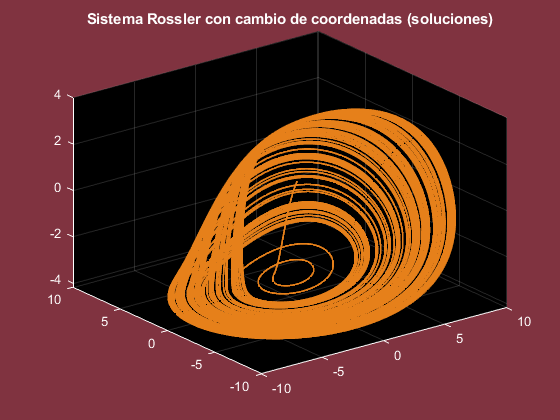

clc
clearvars
close all
format short

global a b c k1 k2 k3;

a=0.2;
b=5;
c=0.2;
k1=1;
k2=2;
k3=3;

ti=0;
tf=1000;
h=0.01;
t=(ti:h:tf);

x0=[1,0.5,0.6,0.7,0.5,0.1]; %Condiciones iniciales
[t,x]=ode23(@ss,t,x0);

%------------Rescritura a nuevas coordenadas----------------
plot3(x(:,1),x(:,2),x(:,3),'color',[0.9 0.5 0.1],'LineWidth',1.5)
set(gca,'color','k','xcolor','w','ycolor','w','zcolor','w')
title('Sistema Rossler con cambio de coordenadas (soluciones)','color','w')
set(gcf,'color',[0.5 0.2 0.25])
grid on

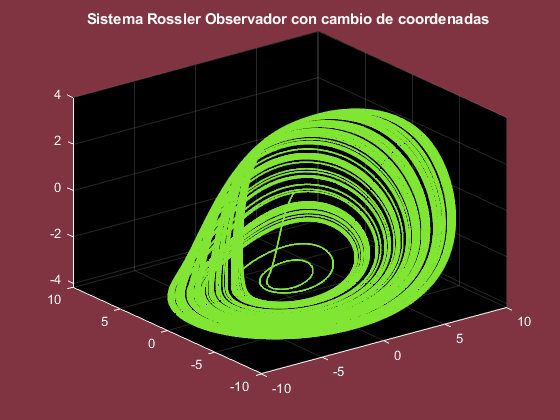



plot3(x(:,4),x(:,5),x(:,6),'color',[0.5 0.9 0.2],'LineWidth',1.5)
set(gca,'color','k','xcolor','w','ycolor','w','zcolor','w')
title('Sistema Rossler Observador con cambio de coordenadas ','color','w')
set(gcf,'color',[0.5 0.2 0.25])
grid on

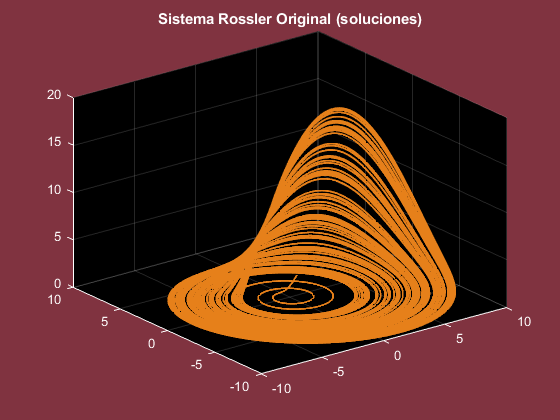


%------------Regreso a las coordenadas orginales----------------

plot3(x(:,1),x(:,2),exp(x(:,3)),'color',[0.9 0.5 0.1],'LineWidth',1.5)
set(gca,'color','k','xcolor','w','ycolor','w','zcolor','w')
title('Sistema Rossler Original (soluciones)','color','w')
set(gcf,'color',[0.5 0.2 0.25])
grid on

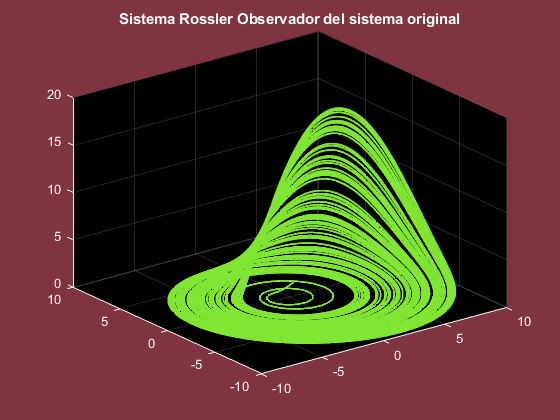


plot3(x(:,4),x(:,5),exp(x(:,6)),'color',[0.5 0.9 0.2],'LineWidth',1.5)
set(gca,'color','k','xcolor','w','ycolor','w','zcolor','w')
title('Sistema Rossler Observador del sistema original','color','w')
set(gcf,'color',[0.5 0.2 0.25])
grid on

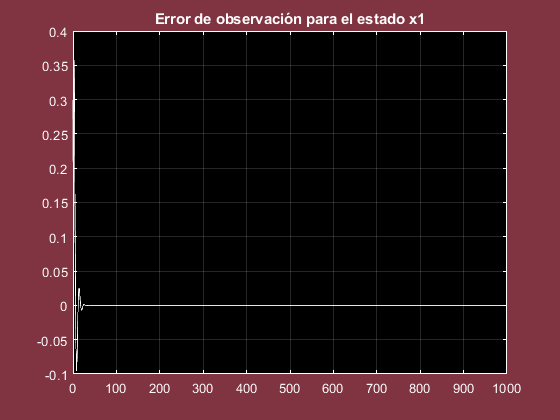



%---------------------Errores---------------
plot(t,x(:,1)-x(:,4),'w')
title('Error de observación para el estado x1','color','w') 
set(gca,'color','k','xcolor','w','ycolor','w','zcolor','w')
grid on

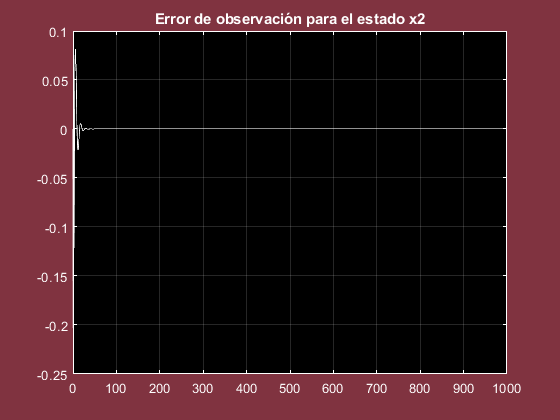



plot(t,x(:,2)-x(:,5),'w')
title('Error de observación para el estado x2','color','w') 
set(gca,'color','k','xcolor','w','ycolor','w','zcolor','w')
grid on

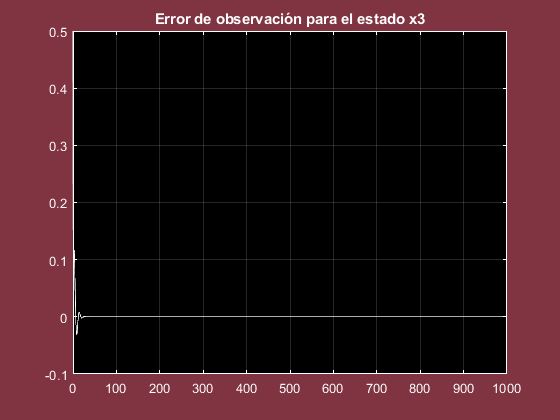


plot(t,x(:,3)-x(:,6),'w')
title('Error de observación para el estado x3','color','w') 
set(gca,'color','k','xcolor','w','ycolor','w','zcolor','w')
grid on

Sistema se Rossler

                                                       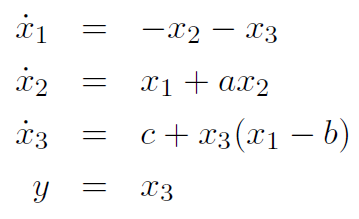

Res escritura del sistema en nuevas coordenadas

                                                         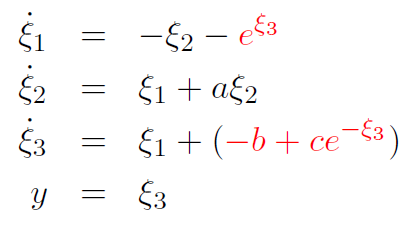

Observador

                                             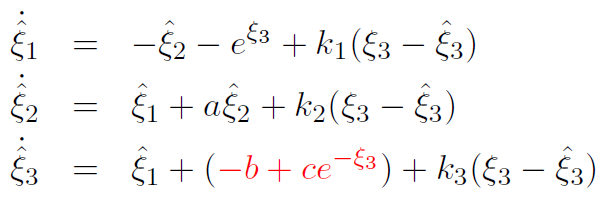

function dX=ss(t,X)

global a b c k1 k2 k3;

e3=X(3)-X(6);

xp1= -X(2)-exp(X(3));
xp2= X(1) +a*X(2);
xp3= X(1) + (-b + c*exp(-X(3)));
xpg1= -X(5) - exp(X(3)) + k1*e3;
xpg2 = X(4) +a*X(5) + k2*e3;
xpg3= X(4) + ( -b + c*exp(-X(3))) + k3*e3;
dX=[xp1;xp2;xp3;xpg1;xpg2;xpg3];


end